clc
clear all
close all


f = fred

f =   fred のプロパティ:

                 URL: 'https://fred.stlouisfed.org/'
                  IP: []
                Port: []
        DatetimeType: []
    DataReturnFormat: []


startdate = '01/01/1995';
enddate = '10/01/2022';

d1 = fetch(f,'CLVMNACSCAB1GQES',startdate,enddate)

d1 = フィールドをもつ struct :
                 Title: ' Real Gross Domestic Product for Spain'
              SeriesID: ' CLVMNACSCAB1GQES'
                Source: ' Eurostat'
               Release: ' National Accounts - GDP (Eurostat)'
    SeasonalAdjustment: ' Seasonally Adjusted'
             Frequency: ' Quarterly'
                 Units: ' Millions of Chained 2010 Euros'
             DateRange: ' 1995-01-01 to 2023-01-01'
           LastUpdated: ' 2023-05-16 4:01 AM CDT'
                 Notes: ' Eurostat unit ID: CLV10_MNAC Eurostat item ID: B1GQ Eurostat country ID: ES  Copyright, European Union, http://ec.europa.eu, 1995-2016. Complete terms of use are available at https://ec.europa.eu/geninfo/legal_notices_en.htm (https://ec.europa.eu/geninfo/legal_notices_en.htm).'
                  Data: [112×2 double]


d2 = fetch(f,'JPNRGDPEXP',startdate,enddate)

d2 = フィールドをもつ struct :
                 Title: ' Real Gross Domestic Product for Japan'
              SeriesID: ' JPNRGDPEXP'
                Source: ' JP. Cabinet Office'
               Release: ' National Accounts of Japan'
    SeasonalAdjustment: ' Seasonally Adjusted'
             Frequency: ' Quarterly'
                 Units: ' Billions of Chained 2015 Yen'
             DateRange: ' 1994-01-01 to 2023-01-01'
           LastUpdated: ' 2023-06-07 6:56 PM CDT'
                 Notes: ' Copyright, 2016, Cabinet Office of Japan.'
                  Data: [112×2 double]



q = d1.Data(:,1);

sy = d1.Data(:,2);
jy = d2.Data(:,2);





%[trend, cycle] = hpfilter(log(y), 1600);
[cyclesy, trendsy] = qmacro_hpfilter(log(sy), 1600);
[cyclejy, trendjy] = qmacro_hpfilter(log(jy), 1600);

% compute sd(y) (from detrended series)
sysd = std(cyclesy)*100;
jysd = std(cyclejy)*100;

corrcoef(cyclesy,cyclejy)

ans =     1.0000    0.6069
    0.6069    1.0000



disp(['Percent standard deviation of detrended log real GDP: ', num2str(sysd),'.']); disp(' ')

Percent standard deviation of detrended log real GDP: 2.7223.
 


disp(['Percent standard deviation of detrended log real GDP: ', num2str(jysd),'.']); disp(' ')

Percent standard deviation of detrended log real GDP: 1.6209.
 


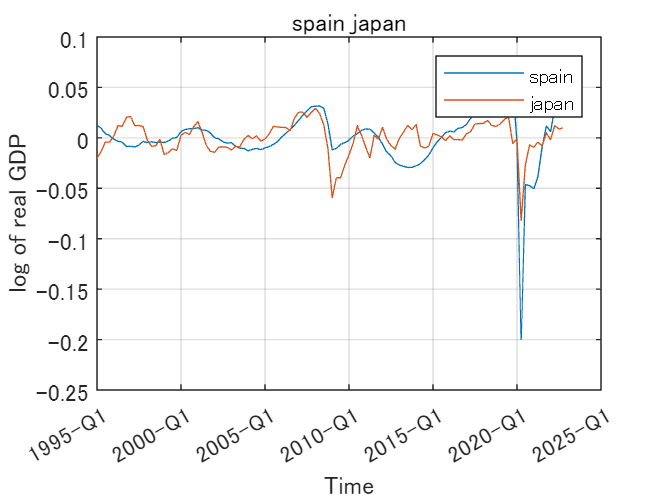

plot(q, cyclesy,q, cyclejy)
datetick('x','yyyy-qq')
title('spain japan')
ylabel('log of real GDP')
xlabel('Time')
legend('spain','japan')
grid on